# @EMAT30007 Applied Statistics

# Worksheet 2: Parameter estimation

## Nikolai Bode

This worksheet focusses on the material covered in Lecture 2: Methods to estimate the parameter values or quantities of a probability distribution.

## 1. Maximum Likelihood (ML)

**ML estimate for the parameter of a Bernoulli distribution**

Estimate the parameter $p$ of a Bernoulli distribution from a sample of $n=10$ observations using the ML method:

- Generate a sample $x$ of size $n=10$ from a Bernoulli distribution with parameter $p=0\ldotp 75$ (as for Worksheet 1, you can use `makedist`).

- Compute and plot the Likelihood function for the sample $x$, $L\left(p;x\right)=\prod_{i=1}^n P_x \left(x_i ;p\right)$.

- Compute and plot the log-Likelihood function for the sample $x$, $\log \left(L\left(p\right)\right)=\sum_{i=1}^n \log \;P_x \left(x_i ;p\right)$.

- Use Matlab's `fminsearch` to find $p_L$, the value of $p$ that maximises $L\left(p\right)$, and $p_{\textrm{logL}}$, the value of p that maximises $\log \;L\left(p\right)$.

- Compute $\hat{p_{\textrm{MLE}} } =\frac{1}{n}\sum_i x_i \;$the analytical ML estimate for the sample $x$ . Does $\hat{p_{\textrm{MLE}} } =p_L =p_{\textrm{logL}}$? In general, $\hat{p_{\textrm{MLE}} } \not= p$, the true parameter value. Why?

- Increase the sample size $n=100,1000,\ldotp \ldotp \ldotp$ and observe the likelihood functions and the estimates of $p$. What do you notice?

- Check that Matlab's `mle` function gives the same result you found.

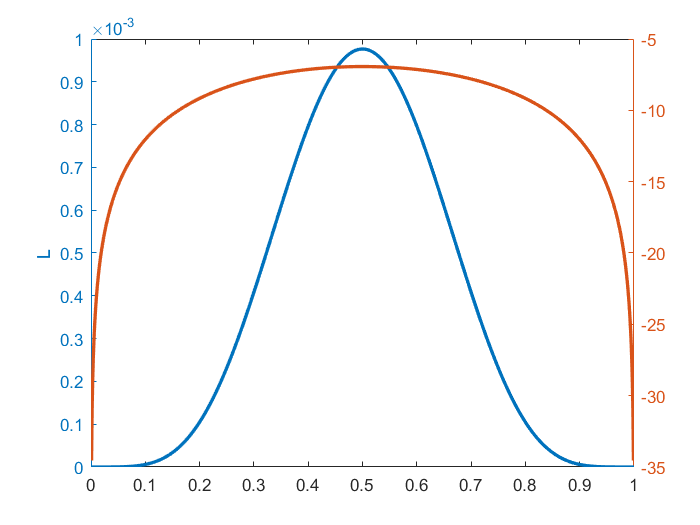

p_true = 0.75;
pd = makedist('Binomial', 'p', p_true);
% remember that the bernoulli distribution is a special case of the binomial distirbtuion
x = random(pd, 1, 10);
% define the likelihood for the bernoulli distribution
likelihood = @(p) prod(p.^x .* (1-p).^(1-x));
% define the log-likelihood for the bernoulli distribution
loglikelihood = @(p) sum(x .* log(p) + (1-x) .* log(1-p));
% compute likelihood
p = 0: 0.001: 1;
likelihoods = zeros(1, length(p));
loglikelihoods = zeros(1, length(p));
for i = 1:length(p)
likelihoods(i) = likelihood(p(i));
loglikelihoods(i) = loglikelihood(p(i));
end
% plot
clf;
yyaxis left
plot(p, likelihoods, '-', 'Linewidth', 2)
ylabel('L') % y-axis label
yyaxis right
plot(p, loglikelihoods, '-', 'Linewidth', 2)
hold on

% Find p that maximises L (i.e., minimises -L)
negL = @(x) likelihood(x) * -1;
p_L = fminsearch(negL, 0) % initial value of p is 0

p_L = 0.5000

% Find p that maximises logL (i.e., minimises -logL)
neglogL = @(x) loglikelihood(x) * -1;
% fminsearch(neglogL, 0)
p_logL = fminsearch(neglogL, 0)

p_logL = 0.5000

Some times `fminsearch` may not converge and it returns wrong estimates. Starting from a different initial condition can solve the problem. In other cases this coul be due to numerical errors, for example when the function to be optimised has values beyond the Matlab's numerical precision -- this can happen for Likelihood functions for large samples (why?).

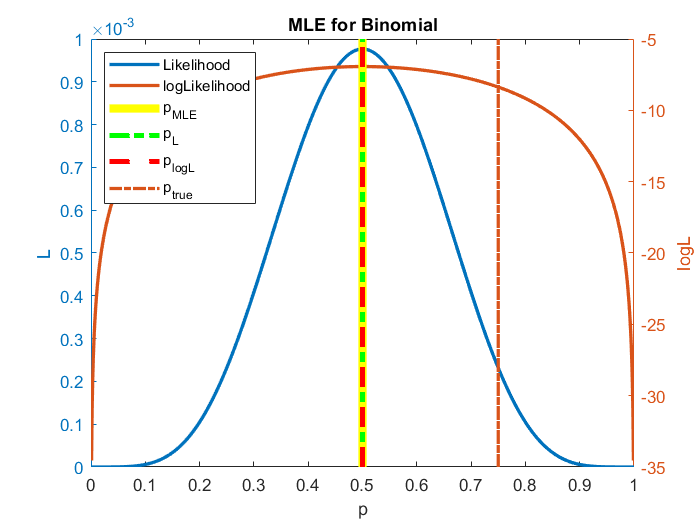

p_hat = mean(x);
yL = get(gca,'YLim');
line([p_hat,p_hat],yL,'Color','yellow','LineWidth',5,'LineStyle','-')
hold on
line([p_L,p_L],yL,'Color','green','LineWidth',3,'LineStyle','-.')
hold on
line([p_logL,p_logL],yL,'Color','red','LineWidth',3,'LineStyle','--')
hold on
line([p_true,p_true],yL,'LineWidth',2,'LineStyle','-.')
legend('Likelihood', 'logLikelihood', 'p_{MLE}', 'p_{L}', 'p_{logL}', 'p_{true}', 'Location','northwest')
title('MLE for Binomial') % title for plot
xlabel('p') % x-axis label
ylabel('logL') % y-axis label

Run the code a few times to see how likelihoods change for different data samples and for different sizes $n$.

$\hat{p_{\textrm{MLE}} } =p_L =p_{\textrm{logL}}$ because, as explained in the lecture, the likelihood and log-likelihood have the same (arg)maximum (`log` is strictly increasing) and $p_{\textrm{MLE}}$ is the exact value.

$\hat{p_{\textrm{MLE}} } \not= p$ because the sample $x$ is subject to randomness and especially for small $n$ it can have much higher of fewer 1s (`heads') than expected. As $n$ is increased the average number of 1s tend to the expected true value $p$ (because of the law of large numbers).

Also, when $n$ is large `fminsearch` has problems in finding the correct maximum of the Likelihood because of numerical errors arising from the fact that $L$ , which is the product of many numbers smaller than 1, becomes extremely small (e.g. ${10}^{-23}$), beyond Matlab's numerical precision. The function $\log \;L$ instead does not suffer from this problem, so it should be used to numerically estimate the maximim for large $n$.

% Matlab's MLE function
mle(x,'distribution','Bernoulli')

ans = 0.5000

**ML estimate for the parameters of a Normal distribution**

Follow the same steps as above to estimate the parameters $\mu$ and $\sigma$ of a Normal distribution from a sample of $n=10$ observations using the ML method:

- Generate a sample $x$ of size $n=10$ from a Normal distribution with parameters $\mu =0$ and $\sigma =1$.

- Define the Likelihood and log-Likelihood functions for the sample $x$ as a function of parameters $\mu$ and $\sigma$ (`normpdf(x, mu, sigma)` gives the value of the Normal PDF at $x$).

- Use Matlab's `fcontour(likelihood, [-1 1 0 2])` to plot the Likelihood function for the sample $x$, $L\left(\mu ,\sigma ;x\right)=\prod_{i=1}^n P_X \left(x_i ;\mu ,\sigma \right)$.

- Use Matlab's fminsearch to find $\left(\mu_L ,\sigma_L \right)$, the values of the parameters that maximise $L\left(\mu ,\sigma \right)$,

- Compute the analytical ML estimate $\left({\hat{\mu} }_{\textrm{MLE}} ,{\hat{\sigma} }_{\textrm{MLE}} \right)$. Is $\left({\hat{\mu} }_{\textrm{MLE}} ,{\hat{\sigma} }_{\textrm{MLE}} \right)=\left(\mu_L ,\sigma_L \right)$? Why?

- Increase the sample size $n=100,1000,\ldotp \ldotp \ldotp$ and observe the likelihood functions and the estimates of $\mu$ and $\sigma$. What do you notice?

- Check that Matlab's `mle` function gives the same result you found.

***Solution:***

% Solution


## Compute MLE by hand

The PDF of a continuous RV $X$ is $P_X \left(x\right)=\frac{\theta }{x^{\theta +1} }$ for $x>1$ and $0$ otherwise.

- Find the Maximum Likelihood estimator of $\theta$ analytically. Make sure to check that is a maximum of the loglkelihood.

- Use the code` x = rand(1, n) .^ (-1/theta)`; to draw a sample $x$ of size $n=10000$ from the PDF of $X$ with parameter `theta=3.5`. (Where does this code come from?)

- Translate the estimator computed in step 1. into Matlab code and use it to estimate `theta` for the sample $x$ obtained in step 2.

***Solution***

## 2. Method of Moments (MoM)

**MoM estimate for the parameters of a Poisson distribution**

1. Calculate ${\hat{\lambda} }_{\textrm{MoM}}$ the method of moments estimator for the parameter $\lambda$ of a Poisson distribution with PMF $P_X \left(x;\lambda \right)=\frac{e^{-\lambda } \lambda^x }{x!}$, with $x=0,1,\ldotp \ldotp \ldotp$and $\lambda >0$.

2. Generate a sample $x$ of $n=10$ observations from a Poisson distribution with parameter $\lambda =10$ and estimate it using ${\hat{\lambda} }_{\textrm{MoM}}$, the estimator derived in 1.

3. Consider increasing sample sizes $n=100,1000$ and for each $n$ draw 1000 samples, compute their 1000 MoM estimates ${\hat{\lambda} }_{\textrm{MoM}}$, and calculate the estimates' standard deviation, $\sigma_{\hat{\lambda} }$. Plot $n$ against $\sigma_{\hat{\lambda} }$ and verify that  the "spread" of the estimates decreases as the square root of $n$ , as the sample size increases.

***Solution***

The distribution has one parameter, so we have to compute the first theoretical moment (mean) and equate it to the sample mean $\bar{X}$:


$$E\left(X\right)=\sum_{x=0}^{\infty } P_X \left(x;\lambda \right)x=\sum_{x=1}^{\infty } \frac{e^{-\lambda } \lambda^x x}{x!}=\sum_{x=1}^{\infty } \frac{e^{-\lambda } \lambda^{x-1} \lambda }{\left(x-1\right)!}=\sum_{x=0}^{\infty } \frac{e^{-\lambda } \lambda^x \lambda }{x!}=1\cdot \lambda =\lambda$$


Solving the equation $E\left(X\right)=\bar{X}$ for $\lambda$ we obtain ${\hat{\lambda} }_{\textrm{MoM}} =\bar{X} =\frac{\sum_{i=1}^n x_i }{n}$.

% generate Poisson random sample
lambda = 10;
n = 10000;
x = poissrnd(lambda, 1, n);
% MoM estimate of parameter lambda
mean(x)

ans = 9.9976

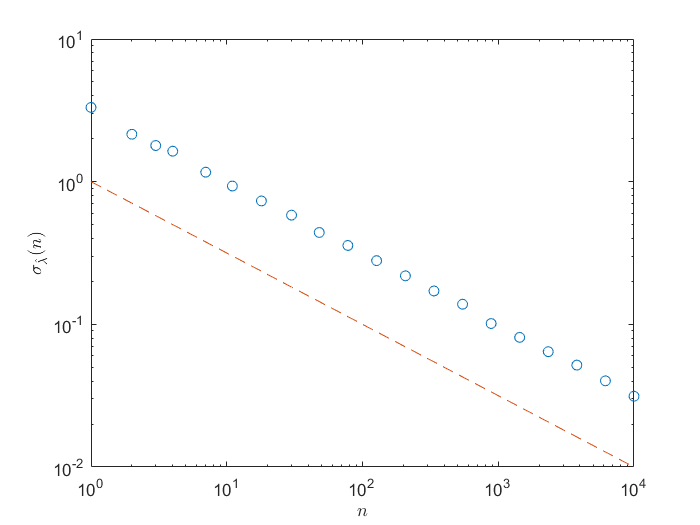

% increasing sample size
ns = round(logspace(0, 4, 20));
s = 1000;
% compute the standard deviation of the estimates for different sample sizes
stdevs = zeros(1, length(ns));
for i = 1:length(ns)
n = ns(i);
estimates = zeros(1, s);
for j = 1:s
x = poissrnd(lambda, 1, n);
estimates(j) = mean(x);
end
stdevs(i) = std(estimates);
end
% plot standard deviation (spread) of estimates against the sample size
clf;
plot(ns, stdevs, 'o');
hold on
plot(ns, ns.^(-0.5), '--');
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');
xlabel('$n$', 'Interpreter', 'latex') % x-axis label
ylabel('$\sigma_{\hat{\lambda}}(n)$', 'Interpreter', 'latex') % y-axis label

## 3. Unbiased estimators

Consider the RV $X$ with the PDF $P\left(x;\sigma \right)=\frac{1}{2\sigma }e^{\frac{-\left|x\right|}{\sigma }}$for $x\in R$.

- Calculate ${\hat{\sigma} }_{\textrm{MLE}}$, the Maximum Likelihood estimator of σ.

- Calculate ${\hat{\sigma} }_{\textrm{MoM}}$, the Method of Moments estimator of σ.

- Do the two methods give the same estimator?

- Check numerically if ${\hat{\sigma} }_{\textrm{MLE}}$ and ${\hat{\sigma} }_{\textrm{MoM}}$ look ubiased, asymptotically ubiased or biased: draw $20000$ samples of various sizes, $n=\left\lbrack 5,10,100,1000\right\rbrack$, and plot the histograms and means of the distributions of the estimates for the different $n$. Is there a better estimator? To generate $n$ random numbers from the PDF $P_X \left(x;\sigma \right)$, use the code `x = exprnd(sigma, 1, n) .* (2 * binornd(1, 0.5, 1, n) - 1)` (why?).

***Solution***

## 4. Comparison of estimators for the mean of non-skewed and skewed distributions

Use simulations to investigate whether the mean or median is a better estimator of the mean (parameter $\mu$) of a Normal distribution. Compare the two estimators by analysing (1) bias and (2) standard deviation (spread) of the estimates.

***Solution***

Use simulation to compare the use of the sample mean and median as estimators of the mean (parameter λ) of an Exponential distribution. Again, compare the two estimators by analysing (1) bias and (2) standard deviation (spread) of the estimates.

***Solution***